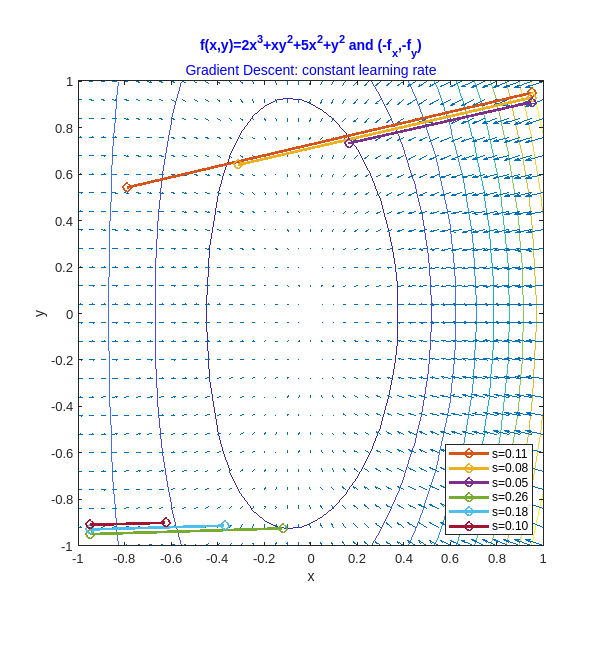

n =2;

[x,y]=meshgrid(-1:0.05:1,-1:0.08:1);
z=2*x.^3+x.*y.^2+5*x.^2+y.^2;

X=zeros(2,n);
X(:,1)=[0.95;0.95];
s=0.11;
for j=1:n-1
    X(1,j+1)=X(1,j)-s*(6*X(1,j)^2+X(2,j)^2+10*X(1,j));
    X(2,j+1)=X(2,j)-s*(2*X(1,j)*X(2,j)+2*X(2,j));
end

Y=zeros(2,n);
Y(:,1)=[0.95;0.93];
s=0.08;
for j=1:n-1
    Y(1,j+1)=Y(1,j)-s*(6*Y(1,j)^2+Y(2,j)^2+10*Y(1,j));
    Y(2,j+1)=Y(2,j)-s*(2*Y(1,j)*Y(2,j)+2*Y(2,j));
end

Z=zeros(2,n);
Z(:,1)=[0.95;0.91];
s=0.05;
for j=1:n-1
    Z(1,j+1)=Z(1,j)-s*(6*Z(1,j)^2+Z(2,j)^2+10*Z(1,j));
    Z(2,j+1)=Z(2,j)-s*(2*Z(1,j)*Z(2,j)+2*Z(2,j));
end

U=zeros(2,n);
U(:,1)=[-0.95;-0.95];
s=0.26;
for j=1:n-1
    U(1,j+1)=U(1,j)-s*(6*U(1,j)^2+U(2,j)^2+10*U(1,j));
    U(2,j+1)=U(2,j)-s*(2*U(1,j)*U(2,j)+2*U(2,j));
end

V=zeros(2,n);
V(:,1)=[-0.95;-0.93];
s=0.18;
for j=1:n-1
    V(1,j+1)=V(1,j)-s*(6*V(1,j)^2+V(2,j)^2+10*V(1,j));
    V(2,j+1)=V(2,j)-s*(2*V(1,j)*V(2,j)+2*V(2,j));
end

W=zeros(2,n);
W(:,1)=[-0.95;-0.91];
s=0.1;
for j=1:n-1
    W(1,j+1)=W(1,j)-s*(6*W(1,j)^2+W(2,j)^2+10*W(1,j));
    W(2,j+1)=W(2,j)-s*(2*W(1,j)*W(2,j)+2*W(2,j));
end

contour(x,y,z,10)
pbaspect([1 1 1])
title('f(x,y)=2x^3+xy^2+5x^2+y^2 and (-f_x,-f_y)','Gradient Descent: constant learning rate','Color','blue','FontSize',11)
xlabel('x')
ylabel('y')
[u,v] = gradient(z);
hold on
quiver(x,y,-u,-v)
plot(X(1,:),X(2,:),'-o', ...
    Y(1,:),Y(2,:),'-o', ...
    Z(1,:),Z(2,:),'-o', ...
    U(1,:),U(2,:),'-o', ...
    V(1,:),V(2,:),'-o', ...
    W(1,:),W(2,:), ...
    '-o','LineWidth',2)
legend('','','s=0.11','s=0.08','s=0.05','s=0.26','s=0.18','s=0.10','Location','southeast');
hold off
set(gcf,'Position',[1000,200,600,650]);
saveas(gcf,'descent2.png');
saveas(gcf,'descent2.eps');

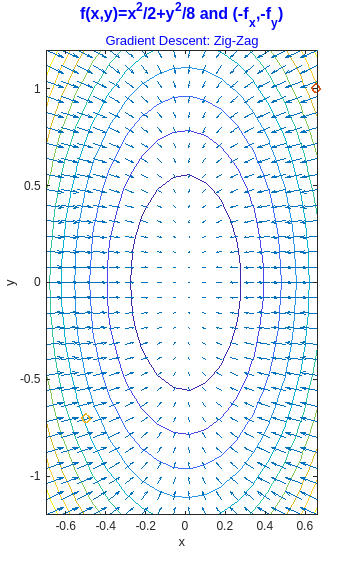

N = 1;
[x,y]=meshgrid(-0.7:0.08:0.7,-1.2:0.08:1.2);
z=(x.^2)/2+(y.^2)/8;

X=zeros(2,N);
Y=zeros(2,N);
X(:,1)=[0.65;1];
Y(:,1)=[-0.5;-0.7];
if N>1
    for j=1:N-1
    s=(X(1,j)^2+X(2,j)^2/16)/(X(1,j)^2+X(2,j)^2/64);
    X(1,j+1)=(1-s)*X(1,j);
    X(2,j+1)=(1-s/4)*X(2,j);
    t=(Y(1,j)^2+Y(2,j)^2/16)/(Y(1,j)^2+Y(2,j)^2/64);
    Y(1,j+1)=(1-t)*Y(1,j);
    Y(2,j+1)=(1-t/4)*Y(2,j);
    end
end

contour(x,y,z,10)
pbaspect([1 12/7 1])
title('f(x,y)=x^2/2+y^2/8 and (-f_x,-f_y)','Gradient Descent: Zig-Zag','Color','blue','FontSize',12)
xlabel('x')
ylabel('y')
[u,v] = gradient(z);
hold on
quiver(x,y,-u,-v)
plot(X(1,:),X(2,:),'-o',Y(1,:),Y(2,:),'-o','LineWidth',2)
hold off
set(gcf,'Position',[1000,200,350,580]);
saveas(gcf,'zigzag.png');
saveas(gcf,'zigzag.eps');